%根据一个笼腔内可容纳的盖子数m，推断出构型数目(去除对称的重复结构)
clc;
clear all;

A=[];
B=[];
C=[];
nmax=6;


for m=2:4 %笼腔内最多含m个盖子
    %找出m可能的对映互锁结构
    B=[];
    for n=2:nmax
        AM_all=adj_mat(n);
        count=0;
        for i=1:size(AM_all,3)
            AM=AM_all(:,:,i);
            Matrix=rot90(AM,1);
            if cap_num(AM)<=m
                if issymmetric(Matrix)
                    count=count+1;
                else
                    count=count+0.5;
                end
            end
        end

        B=[B,count];
    end    
    C=[C;B];
end


A=[2:nmax];
C;

b=bar(A,C,0.6,LineWidth=1.5)

b =   1×3 Bar 数组:

    Bar    Bar    Bar


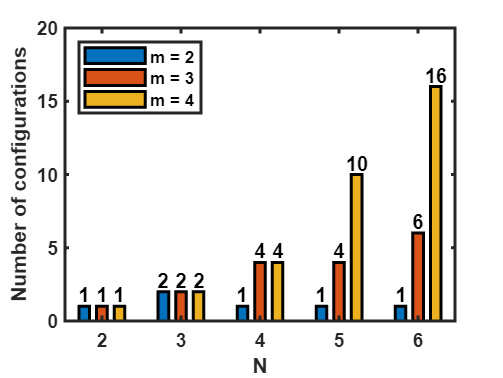

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('N','FontName','arial','FontWeight','bold'); 
ylabel('Number of configurations','FontName','arial','FontWeight','bold');
xtips2 = b(1).XEndPoints;
 ytips2 = b(1).YEndPoints;
 labels2 = string(b(1).YData);
 text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom','FontWeight','bold','FontName','arial')
  xtips2 = b(2).XEndPoints;
 ytips2 = b(2).YEndPoints;
 labels2 = string(b(2).YData);
 text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom','FontWeight','bold','FontName','arial')
  xtips2 = b(3).XEndPoints;
 ytips2 = b(3).YEndPoints;
 labels2 = string(b(3).YData);
 text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom','FontWeight','bold','FontName','arial')
 legend('m = 2','m = 3','m = 4','Location','northwest')

function m=cap_num(AM)
%从AM分析一个笼内最多塞几个盖子
cap=[];
for i=1:size(AM,2)
    cap=[cap,sum(AM(:,i))];
end
m=max(cap);
end
%-------------------------------------------------
function interwoven=devide(AM)
%将邻接矩阵AM划分成多个闭锁部分的串联
%interwoven=[1 3;2 4;3 5]代表(1,2,3)(2,3,4)以及(3,4,5)闭锁
U=triu(AM);
i0=1;
S=[];
for i0=1:size(AM,1)-1
for i=i0+1:1:size(AM,1)
    if U(i0,i)==1 
       if i==size(AM,1)
          S=[S;i];
       else
         if U(i0,i+1)==0
            S=[S;i];
         end
       end
    end    
end
end
Q=[reshape(1:size(AM,1)-1,size(AM,1)-1,1),S];

row=1;
while row<size(AM,1)-1
    if Q(row,2)==Q(row+1,2)
        Q(row+1,:)=[];
    else
        row=row+1;
    end

    if row==size(Q,1)
        break
    end
end
interwoven=Q;
end

%-------------------------------------------------
function w=wiener(AM);
%给出邻接矩阵AM的wiener index
a=[];
b=[];
distance=[];
S=devide(AM);
for i=1:size(AM)-1
    for j=i+1:size(AM)
        row=1;
        while row<=size(S,1)
            if find(S(row,1):S(row,2)==i)
                a=[a,row];
            end

            if find(S(row,1):S(row,2)==j)
                b=[b,row];
            end
            row=row+1;
        end

        if isempty(intersect(a,b))
            distance=[distance,b(1)-a(end)+1];
        else
            distance=[distance,1];
        end
        a=[];
        b=[];
    end
end

distance;
w=sum(distance);
end

%-------------------------------------------------
function BM=border(n)
%给定阶数n，生成对映的边界矩阵BM（border matrix）
%该矩阵对映了邻接矩阵AM上三角矩阵中处于0和1边界中1的位置
   BM=zeros(n);

if n==2
   BM(:,:,end+1)=[0 1;0 0];
end

if n>2
   A=border(n-1);
   C=zeros(1,n);
   for i=1:size(A,3)
        B=[zeros(n-1,1),A(:,:,i)];
        for j=2:find(B(1,:)==1)
            C(1,j)=1;
            BM(:,:,end+1)=[C;B];
            C=zeros(1,n);
        end
   end
end
BM(:,:,1)=[];
end
%-------------------------------------------------
function AM=adj_mat(n)
%根据边界矩阵BM，写出n阶所有邻接矩阵AM 
BM=border(n);
AM=zeros(n);

for i=1:size(BM,3)
    A=BM(:,:,i);
    for j=1:n-1
        for k=j+1:find(A(j,:)==1)
            A(j,k)=1;
        end
    end
    A=A+A';
    AM(:,:,end+1)=A;
end
AM(:,:,1)=[];
end

%-------------------------------------------------
function count=num_config(n)
%根据给定的n，给出相应的构型数目（去除对称的结构）
AM_all=adj_mat(n);

count=0;
for i=1:size(AM_all,3)
    AM=AM_all(:,:,i);
    Matrix=rot90(AM,1);
    if issymmetric(Matrix)
        count=count+1;
    else
        count=count+0.5;
    end
end

end












